clc
clear all

## Part 1: Chromo Modal Dispersion

**NecessaryConstants: **

c = 3*10^8; 
n = 1; % refractive index of the cavity is that of free space
L = .5; % Length of cavity is 50 cm
R = .9; % Default reflectivity is 90%
lambda = 800*10^-9; % center wavelength
v_0 = c/lambda; % center frequency
k = 2*pi/lambda; % free space wave vector
rtphase = 2*k*L;

**a) **

First, the free spectral range (FSR) is given as: $\textrm{FSR}=\frac{c}{2\textrm{nL}}=\frac{c}{2L}\;\left(\textrm{for}\;n=1\right)$.  

The transmittance of the light in the cavity is given by: 

$T=\frac{\left(1-R_1 \right)\left(1-R_2 \right)}{{\left(1-\sqrt{R_1 R_2 }\right)}^2 +4\sqrt{R_1 R_2 }\sin^2 \left(\textrm{kL}\right)}$, which for equal reflectivities leads to: 

$T=\frac{{\left(1-R\right)}^2 }{{\left(1-R\right)}^2 +4{\mathrm{Rsin}}^2 \left(\mathrm{kL}\right)}$.  In this equation, $\textrm{kL}$ is the phase term for propagation over the length L of the cavity, whereas the round trip phase shift would be represented by $2\textrm{kL}$. Plotting the transmittance versus $\frac{\textrm{kL}}{\pi }$ yields: 

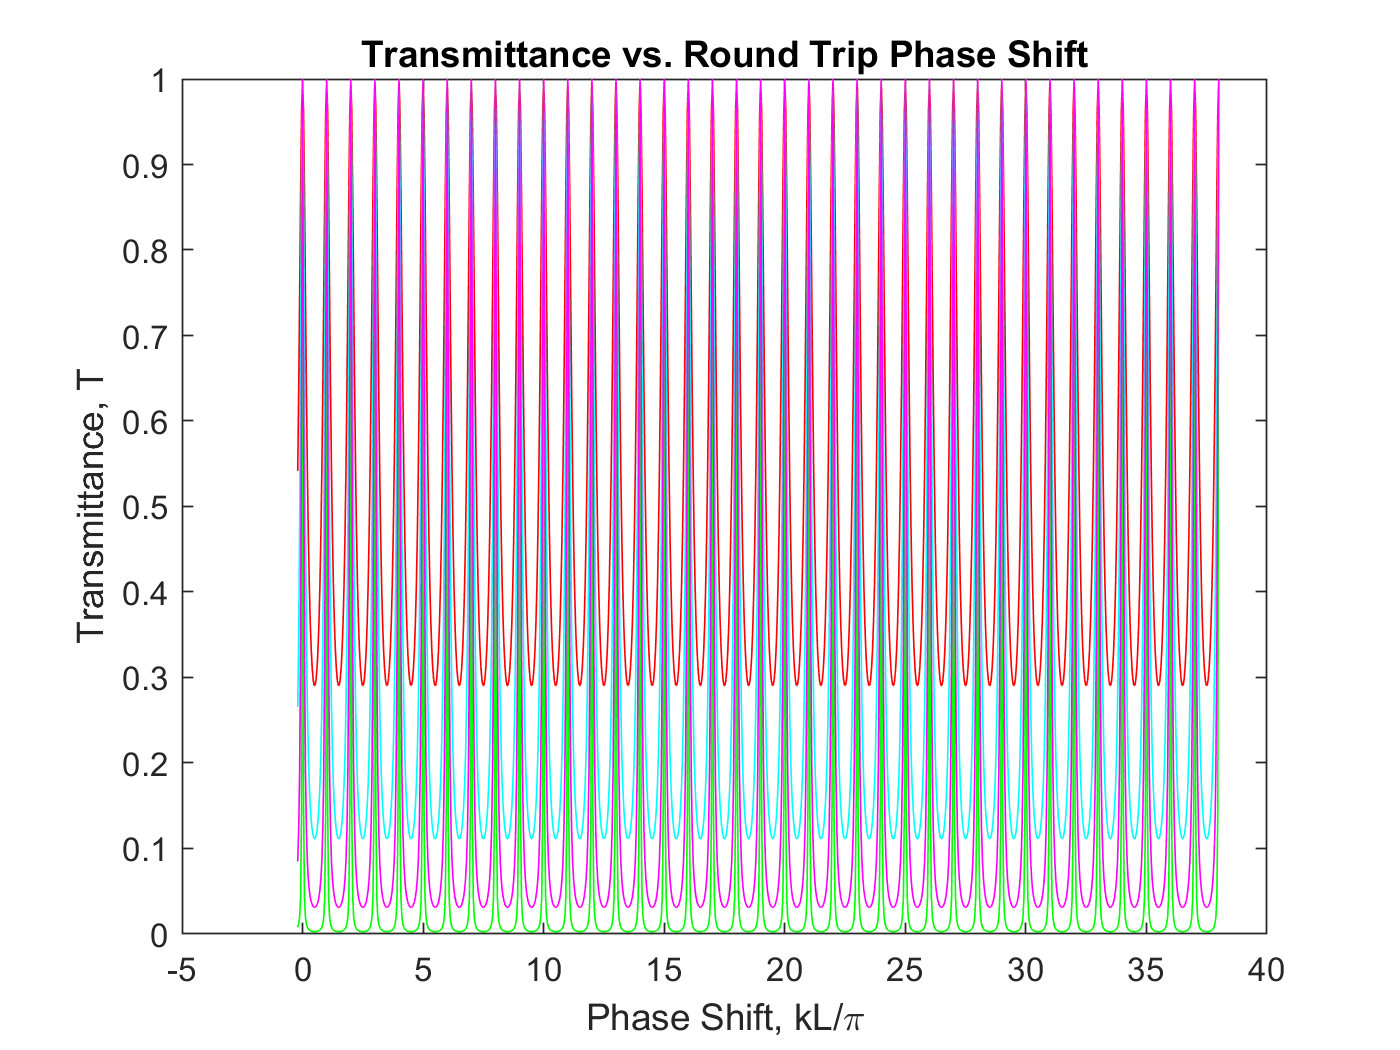

m = -.2:.04:10; % integer m = kl/pi
T1 = (1-R)^2./((1-R)^2+4*R.*(sin(m*pi).^2)); % Transmittance for R = 90%
R = .3;
T2 = (1-R)^2./((1-R)^2+4*R.*(sin(m*pi).^2)); % "  " for R = 30%
R = .5; 
T3 = (1-R)^2./((1-R)^2+4*R.*(sin(m*pi).^2)); % "  " for R = 50%
R = .7;
T4 = (1-R)^2./((1-R)^2+4*R.*(sin(m*pi).^2)); % "  " for R = 70%

plot(m,T1,'g',m,T2,'r',m,T3,'c',m,T4,'m')
xlabel('Phase Shift, kL/\pi')
ylabel('Transmittance, T')
title('Transmittance vs. Round Trip Phase Shift')

**b)**

Next, the mode number for the center wavelength of the cavity is

$m=\frac{2\mathrm{nL}}{\lambda }$, and the precise mode wavelength is given by: $\lambda_m =\frac{2\mathrm{nL}}{m}$.  This gives a corresponding frequency of $\upsilon_m =\frac{c}{\lambda_m }$.  From this, we can find the free spectral range (FSR), or the separation between adjacent modes, $v_m -v_{m-1} =v_f =\frac{c}{2\mathrm{nL}}$.  The cavity finesse is $F=\frac{{\pi R}^{\frac{1}{2}} }{1-R}\mathrm{or}\;\mathrm{alternatively},\frac{v_f }{\delta v_m }$, where $\delta v_m$ is the spectral width, or FWHM of the spectrum.  This leads to the relation $\delta v_m =\frac{v_f }{F}$.  Once we have the free spectral range and FWHM, we can determine the quality factor, Q: $Q=\frac{v_0 }{\delta v_m },\mathrm{where}\;v_0 =\frac{c}{\lambda_0 }\;\left(\mathrm{the}\;\mathrm{center}\;\mathrm{frequency}\right)$

 R = .3:.01:.99; % Reflectivity changes from 30% to 99% 
 m = 2*n*L/lambda % mode number corresponding to 800 nm

m = 1250000

 lambda_m = 2*n*L/m;
 v_m = c/lambda_m

v_m = 3.7500e+14

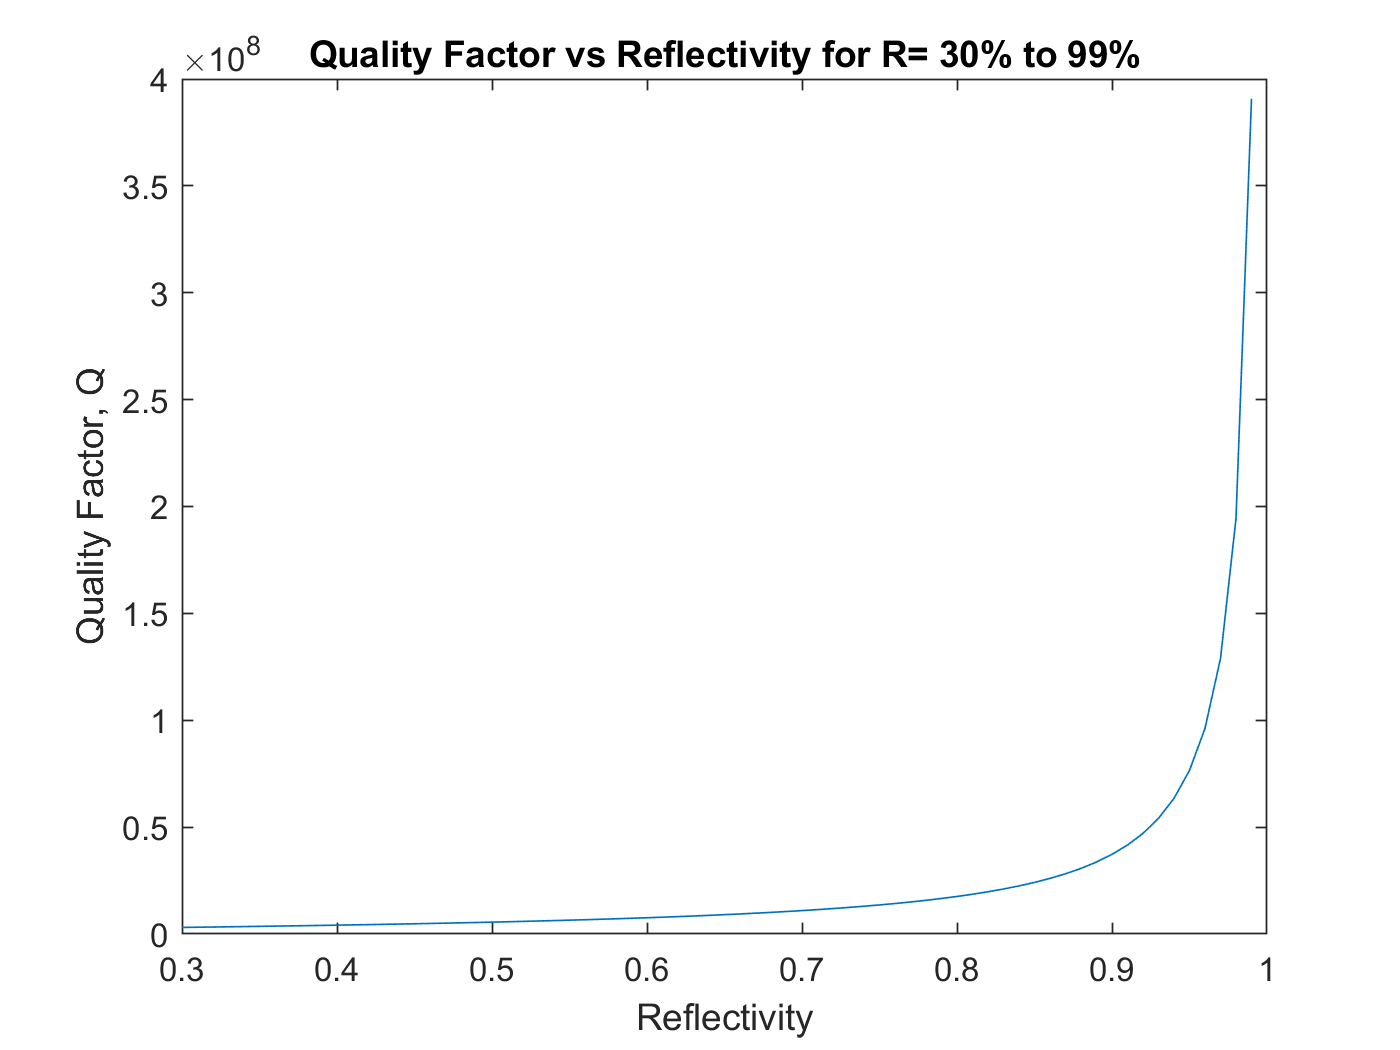

 FSR = c/(2*n*L); % free spectral range
 F = pi.*R.^(1/2)./(1-R);
 dv_m = FSR./F; % Spectral width 
 Q = v_0./dv_m;
 plot(R,Q)
 xlabel('Reflectivity')
 ylabel('Quality Factor, Q')
 title('Quality Factor vs Reflectivity for R= 30% to 99%')

**c) **

When propagation loss is factored into the transmitted spectrum for the cavity, the equation for transmittance becomes: 

$T=\frac{e^{-2\alpha L} \left(1-R_1 \right)\left(1-R_2 \right)}{{\left(1-e^{-2\alpha L} \sqrt{R_1 R_2 }\right)}^2 +4e^{-2\alpha L} \sqrt{R_1 R_2 }{\mathrm{sin}}^2 \left(\mathrm{kL}\right)}=\frac{{e^{-2\alpha L} \left(1-R\right)}^2 }{{\left(1-e^{-2\alpha L} R\right)}^2 +4e^{-2\alpha L} {\mathrm{Rsin}}^2 \left(\mathrm{kL}\right)}$, for $R_1 =R_2 =R$

 R = .9; % Reflectivity back to 90%
 alpha1 = .1; % Propagation loss in m^-1
 alpha2 = 1; 
 alpha3 = 10;
 
 T1 = (1-R)^2./((1-R)^2+4*R.*(sin(rt_phase).^2));

Unrecognized function or variable 'rt_phase'.

**d)**